close all; clear; clc;

# Test Name

**file name**: CP_vs_CT_plots.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
%p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
%diameter = 0 / 12;
%radius = diameter/ 2;               % [ft]
%area = pi * radius^(2);       % [ft^2]

## Most current Master includes all Mega and all P80

master = xlsread('Master_Spreadsheet_v2_20190325_2.xls');

Q = master(:,10);                          % [ft.lbf]
T = master(:,11);                          % [lbf]
rpm = master(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad = rpm .* (pi/30);                       % [rad/sec]
P_out_W = master(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec] 
area = master(:,6);
diameter = master(:,5);
p = master(:,24);


C_T = T ./ (p .* area .* (rad .* (diameter ./ 2)).^2);
C_P = P_out ./ (p .* area .* (rad .* (diameter ./ 2)).^3);
C_Q = Q ./ (p .* area .* (rad .* (diameter ./ 2)).^(2) .* (diameter / 2));

## Comparing Data to Momentum Theory

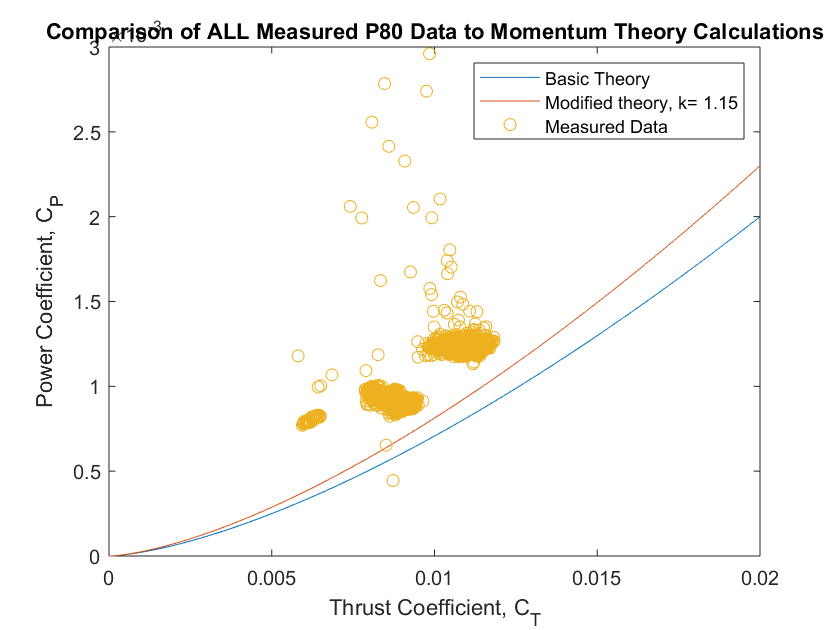

k = 1.15;
C_T_theory = linspace(0, 0.02, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T, C_P, 'o');
title('Comparison of ALL Measured P80 Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.15', 'Measured Data')
xlim([0 0.02]); ylim([0 0.003]);